# Problema 4 - Practic

# 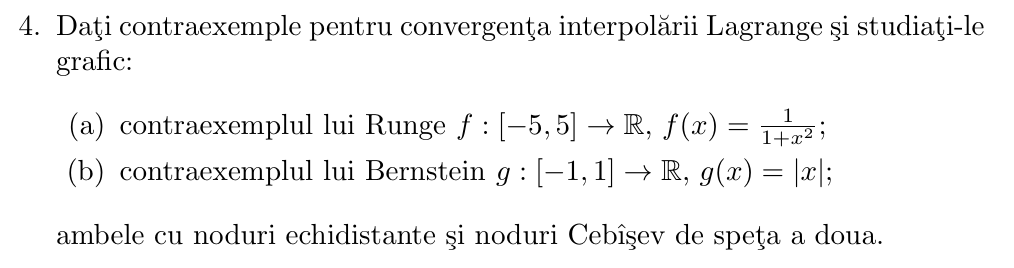

%PB1
function [p_val, p_expr] = lagrangeInterpolation(x_nodes, y_nodes, x_eval)
% INPUT:
%   x_nodes  - vectorul nodurilor de interpolare 
%   y_nodes  - vectorul valorilor functiei in noduri 
%   x_eval   - vectorul punctelor in care se evalueaza polinomul
%
% OUTPUT:
%   p_val    - valorile numerice ale polinomului in punctele x_eval
%   p_expr   - expresia simbolica a polinomului
 
    % Numarul de noduri
    n = length(x_nodes);

    % Asiguram ca x_eval este coloana
    x_eval = x_eval(:);

    % Initializam vectorul rezultat
    p_val = zeros(size(x_eval));

    % Initializare variabila simbolica si polinom simbolic
    syms x;
    p_expr = 0;

    % Construim expresia simbolica si evaluam numeric
    for i = 1:n
        % Initializare L_i(x)
        L_i = 1;
        for j = 1:n
            if j ~= i
                L_i = L_i * (x - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
            end
        end
        % Adunam termenul y_i * L_i(x)
        p_expr = p_expr + y_nodes(i) * L_i;
    end

    % Evaluam numeric in punctele dorite
    for k = 1:length(x_eval)
        p_val(k) = double(subs(p_expr, x, x_eval(k)));
    end

    % Simplificam 
    p_expr = expand(p_expr);  % dezvoltare
end

function comparaInterpolare(f, a, b, descriere)
% INPUT:
%   f         - functia de interpolat
%   a, b      - capetele intervalului
%   descriere - titlu pentru grafic

    % Puncte in care evaluam pentru afisare
    x_eval = linspace(a, b, 500);
    y_real = f(x_eval);  % valoarea reala a functiei

    % Numarul de noduri
    n = 10;

    % ===== Interpolare cu noduri echidistante =====
    x_eq = linspace(a, b, n);    % noduri echidistante
    y_eq = f(x_eq);              % valori functiei in noduri
    [interp_eq, ~] = lagrangeInterpolation(x_eq, y_eq, x_eval);

    % ===== Interpolare cu noduri Chebyshev de speta a II-a =====
    j = 0:n-1;
    x_ch = cos(pi * j / (n - 1));        % noduri pe [-1, 1]
    x_ch = (b - a)/2 * x_ch + (a + b)/2; % remapare in [a, b]
    y_ch = f(x_ch);
    [interp_ch, ~] = lagrangeInterpolation(x_ch, y_ch, x_eval);

    % ===== Plotare =====
    figure;
    plot(x_eval, y_real, 'k-', 'LineWidth', 2); hold on;
    plot(x_eval, interp_eq, 'r--', 'LineWidth', 2);
    plot(x_eval, interp_ch, 'b-.', 'LineWidth', 2);
    plot(x_eq, y_eq, 'ro', 'MarkerFaceColor', 'r');
    plot(x_ch, y_ch, 'bo', 'MarkerFaceColor', 'b');

    legend('f(x)', 'Interpolare echidistanta', 'Interpolare Chebyshev II', ...
        'Location', 'southoutside');
    title(['Interpolare Lagrange - ', descriere]);
    xlabel('x'); ylabel('f(x)');
    grid on;
end

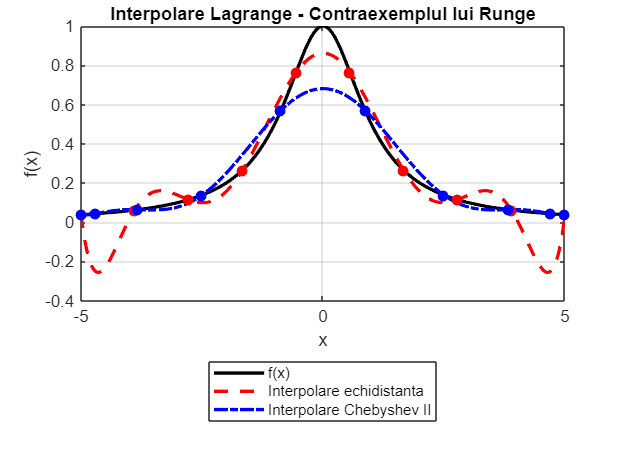

% Functie pentru exemplul lui Runge
f_runge = @(x) 1 ./ (1 + x.^2);
comparaInterpolare(f_runge, -5, 5, 'Contraexemplul lui Runge');

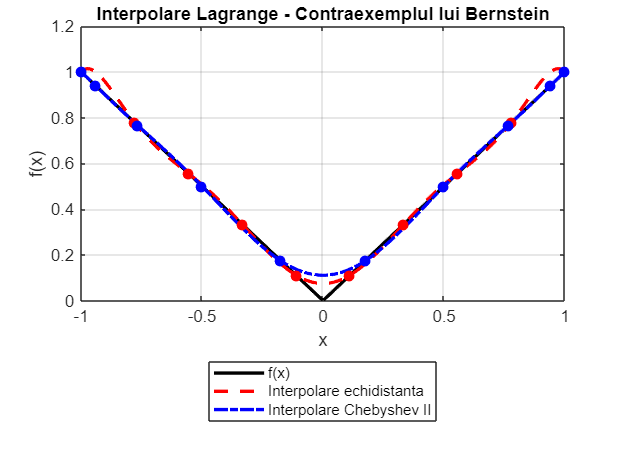


% Functie pentru exemplul lui Bernstein (functie lipsita de derivabilitate in 0)
f_bernstein = @(x) abs(x);
comparaInterpolare(f_bernstein, -1, 1, 'Contraexemplul lui Bernstein');